## Carregando dados de displasia

clear; clc; close all;

Configurations

imageSize = [125 225 3];
dataset = "OSCC400x";

if(startsWith(dataset, "ufu"))
    fileExtensions = '.tif';
elseif strcmp(dataset, 'OSCC400x')
    fileExtensions = ".jpg";
end


Specify the image data augmenter object and input image size.

imds = imageDatastore(fullfile("C:\Users\Diego\Desktop\TCC-NewCode\DataSets\"+dataset, "original"),...
    FileExtensions=fileExtensions,...
    LabelSource="foldernames",...
    IncludeSubfolders=true);

Count and display the number of CXR image samples for each class.

imds.countEachLabel

ans = 2×2 table
      Label      Count
    _________    _____

    healthy       201 
    unhealthy     495 


Set default text and axes tick label interpreters to `"none"`.

initialTextInt = get(groot,"defaulttextInterpreter");
initialAxTickInt = get(groot,"defaultAxesTickLabelInterpreter");
set(groot,defaulttextInterpreter="none")
set(groot,defaultAxesTickLabelInterpreter="none");

Display a random sample of images in the datastore.

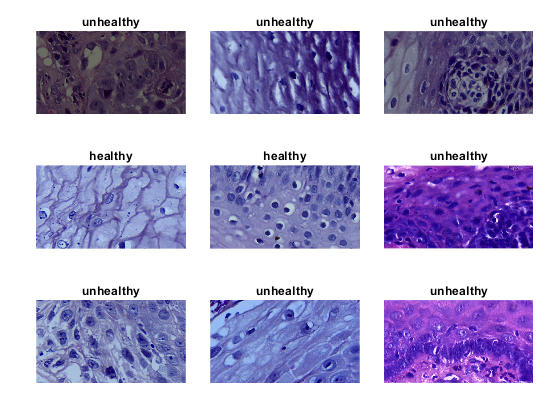

figure
tiledlayout("flow",Padding="compact",TileSpacing="tight")
numTrainImages = numel(imds.Files);
idx = randperm(numTrainImages,9);

for ind = 1:numel(idx)
    nexttile
    imshow(imds.Files{idx(ind)})
    title(string(imds.Labels(idx(ind))))
end

Interactively specify the class label and display random CXR image samples belonging to that class.

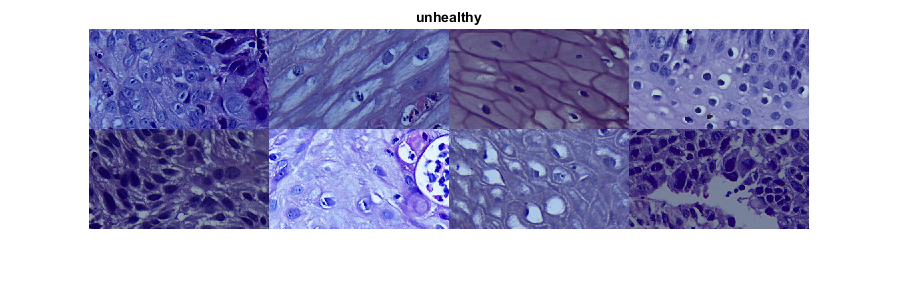

if contains(dataset, "Multiclasse")
    class = 'severe';
elseif strcmp(dataset, 'OSCC400x') || contains(dataset, 'Binario')
    class = 'unhealthy';
end

idxClass = find(imds.Labels==class);
numObsToShow = 8;
idx = randi(length(idxClass),1,numObsToShow);

figure
imshow(imtile(imds.Files(idx),GridSize=[2 4],ThumbnailSize=[100 180]))
title(class)


imds2 = splitEachLabel(imds,2,"randomized");

imds2.countEachLabel

ans = 2×2 table
      Label      Count
    _________    _____

    healthy        2  
    unhealthy      2  


for ind = 1:numel(imds2.Files)
        fileFullPath = imds2.Files{ind};
        newFileFullPath = strrep(fileFullPath,'DataSets\','DataSets\exemploMixupTCC\MixupMaior80\');
        splitUrlFullPath = split(newFileFullPath,"\");
        newFilePath = strrep(newFileFullPath,string(splitUrlFullPath(end)),'');
        createPathIfNotExists(newFilePath);
        img = imread(fileFullPath);
        imwrite(img, newFileFullPath);
end

imds3 = imageDatastore(fullfile("C:\Users\Diego\Desktop\TCC-NewCode\DataSets\exemploMixupTCC\MixupMaior80\"+dataset, "original"),...
    FileExtensions=fileExtensions,...
    LabelSource="foldernames",...
    IncludeSubfolders=true);

imds3.countEachLabel

ans = 2×2 table
      Label      Count
    _________    _____

    healthy        2  
    unhealthy      2  




imdsTrain = generateMixupByLabels(imds3, fileExtensions);